# Determine Is from fit of the V(I)

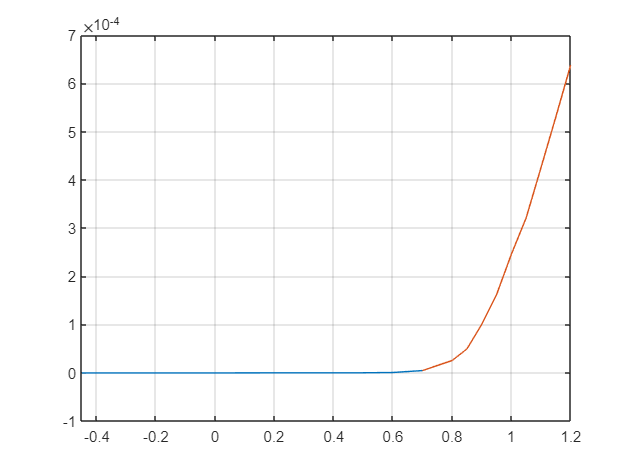

clearvars; close all 
% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\01_IV_curve_chip_spento.txt';
dummyStr = strsplit(LPath, '.');
SPath = [dummyStr{1}, '.mat'];
clear dummyStr

conv = 20e3; %Ohm

if endsWith(LPath, '.lvm')  % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);   %- 1e-7;
elseif endsWith(LPath, '.txt')  % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    Vraw = ivdata.data(:,1);
    Iraw = ivdata.data(:,2)/conv;   
end

start = 5;
V = Vraw(start:end);
I = abs(Iraw(start:end));

% Plot
figure()
plot(Vraw, Iraw, V, I)
xlim([min(Vraw) max(Vraw)])
grid()

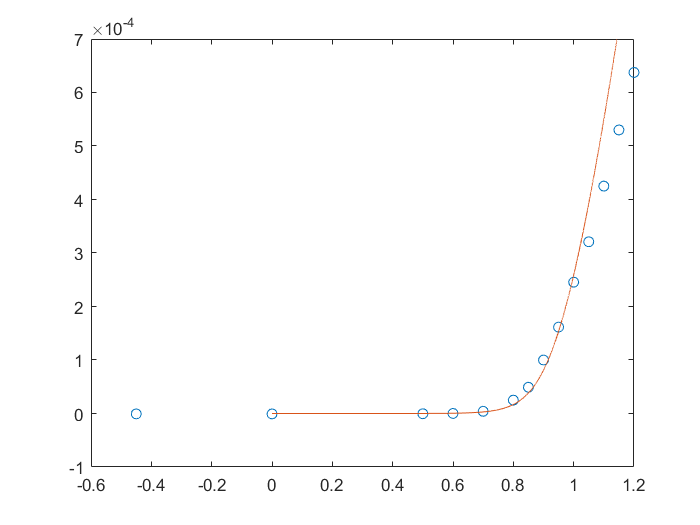

Rs0 = 200;
alpha0 = 18;
Is0 = 1e-11;
p0 = [Rs0, 1/alpha0, 1/Is0];
T0 = 300/(alpha0*0.02585*2);

% C(1) = Rs, C(2) = 1/alpha, C(3) = 1/Is
Vmodel = @(I, C) C(1)*I + C(2)*log(C(3)*I + 1);

II = linspace(0, 7e-4, 10000);
figure()
plot(Vraw, Iraw, 'o')
hold on
plot(Vmodel(II, p0), II)

Fit = esfit(V, esfitV, p0, p0);

-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(C)invIV(I,C(1),C(2),C(3))
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 5.16172e-01   edge 1.00000e-01   initial simplex
iteration   2: value 5.16172e-01   edge 2.00000e+10   reflection
iteration   3: value 5.16172e-01   edge 1.33333e+10   reflection
iteration   4: value 5.16172e-01   edge 1.33333e+10   reflection
iteration   5: value 5.16172e-01   edge 8.88889e+09   reduction
iteration   6: value 5.16172e-01   edge 5.92593e+09   reduction
iteration   7: value 5.16172e-01   edge 1.05350e+10   reflection
iteration   8: value 5.16172e-01   edge 1.05350e+10   reflection
iteration   9: value 5.16172e-01   edge 7.25804e+09   contraction inside
i

% esfit(V, esfitV, p0, p0);

Rs = Fit.pfit(1); alpha = Fit.pfit(2); Is = Fit.pfit(3);
dRs = Fit.pstd(1); dalpha = Fit.pstd(2); dIs = Fit.pstd(3);
mssg = [
    sprintf('Rs = %f +- %f\n', Rs, dRs), ...
    sprintf('alpha = %f +- %f\n', alpha, dalpha), ...
    sprintf('Is = %e +- %e\n', Is, dIs)
    ];
disp(mssg)

Rs = 463.183193 +- 0.000000
alpha = 15.587168 +- 0.000000
Is = 6.073000e-12 +- 4.543419e-13



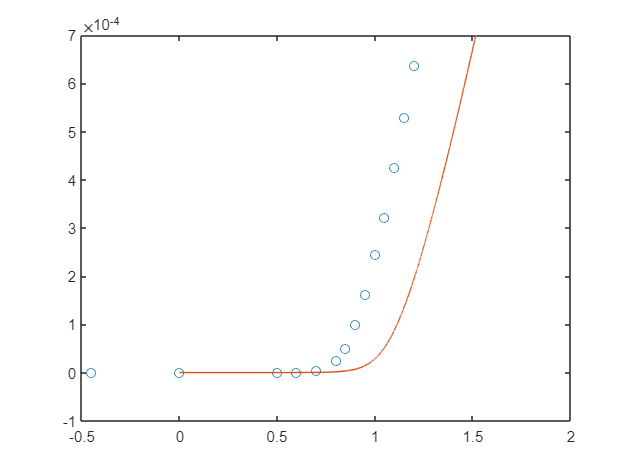

figure()
plot(Vraw, Iraw, 'o')
hold on
plot(VV(Fit.pfit), II)